format shortg

# Oppgave 1

L = 0.750; %H
C = 0.000018;  %F

### a)

rate = 3.40; %A/s

vi har formelen: $\$

Q_c = 2;

Q_c =      2


### b)

Cq = 4.20*10^(-4); %C

### c)

vinkelfrekvensen til en L-C krets er gitt ved formelen: $\omega =\sqrt{\frac{1}{\textrm{LC}}}$

da får vi:

vinkelfrekvensen = sqrt(1/(L*C));
fprintf("vinkelfrekvenser er %g rad/s", signif(vinkelfrekvensen, 3));

vinkelfrekvenser er 272 rad/s

# Oppgave 2

vi får oppgit:

potenislaforskjellen:

V = 65; %V

og vinkelen:

vinkelen = 23.4; %grader

### a)

kan bruke de Broglie sin formel for bølgelengden av en partikkel:


$$\lambda =\frac{h}{p}=\frac{h}{\sqrt{2\cdot m_e \cdot \textrm{eV}}}$$


vet at:

h   = 6.63*10^-34; %J*s
m_e = 9.11*10^-31; %kg
e_v = 1.60*10^-19; %C

da får vi:

bolgelengden = h/(sqrt(2*m_e*e_v*V));
fprintf("bølgelengden er %g m", signif(bolgelengden, 3))

bølgelengden er 1.52e-10 m

### b)

vi kan bruke diffraksjonslikningen: $m\lambda =d\cdot \sin \theta$

og siden vi vet bolgelengden $\lambda$ , $\theta =\textrm{vinkelen}$ og $m=1$ kan vi skrive om formelen og får:


$$d=\frac{\lambda }{\sin \theta }$$


d = bolgelengden/sind(vinkelen);
fprintf("avstanden mellom krystallplanenen er %d = 0,383 nm", d)

avstanden mellom krystallplanenen er 3.835045e-10 = 0,383 nm

### c)

fra formelen i b kan vi utlede en formel for vinkelen: $\sin \theta =\frac{m\cdot \;\lambda }{d}$ og vi får: $\theta =\sin^{-1} \left(\frac{m\cdot \;\lambda }{d}\right)$

m=2;
vinkelen = asind((m*bolgelengden)/d);
fprintf("%.1f grader", vinkelen)

52.6 grader

m=3;
fprintf("%.1f grader", signif((m*bolgelengden)/d,3))

1.2 grader

Vi ser at for m = 2 får vi et nytt maksima med vinkelen 52.6 grader, for m=3 eller høyere får vi et tall over 1 som sinusverdi

# Oppgave 3

vi har verdiene:

c             = 3.00 * 10^8;   %m/s  - lyshastigheten
h             = 6.63 * 10^-34; %J*s
eV_per_joule  = 6.24 * 10^18;  %eV
m_elekotron   = 9.11 * 10^-31; %kg   - massen til elektron
m_a_partikkel = 6.64 * 10^-27; %kg   - massen til alpha-partikkelen
lambda        = 0.20 * 10^-9;  %m    - bølgelengden

### a)

for et foton er energien gitt ved: $E=\frac{\textrm{hc}}{\lambda }$ 

E_foton = ((h*c)/lambda)*eV_per_Joule;
fprintf("Energien til fotonet er %.f eV = 6,21 keV", E_foton);

Energien til fotonet er 6206 eV = 6,21 keV

### b)

for en partikkel med masse har vi: $E=\frac{p^2 }{2m}\;$og $p=\frac{h}{\lambda }$ som gir: $E=\frac{h^2 }{2m\lambda^2 }$

E_elektron = ((h^2)/(2*m_elekotron*lambda^2))*eV_per_Joule;
fprintf("Energien til elektronet er %.1f eV", E_elektron);

Energien til elektronet er 37.6 eV

### c)

bruker samme formel som b) med massen til $\alpha$-partikkelen istendefor elektron-massen.

E_a = ((h^2)/(2*m_a_partikkel*lambda^2))*eV_per_Joule;
fprintf("Energien til alpha-partikkelen er %g eV", signif(E_a, 3));

Energien til alpha-partikkelen er 0.00516 eV

# Oppgave 4

### a)

kan bruke de Broglie sin formel for bølgelengden av en partikkel:


$$\lambda =\frac{h}{p}=\frac{h}{\sqrt{2\cdot m_e \cdot \textrm{eV}}}$$


vet at:

V   = 85; %Volt
h   = 6.63*10^-34; %J*s
m_e = 9.11*10^-31; %kg
e_v = 1.60*10^-19; %C

da får vi:

bolgelengden = h/(sqrt(2*m_e*e_v*V));
fprintf("bølgelengden er %g m", signif(bolgelengden, 3))

bølgelengden er 1.33e-10 m

### b)

bruker samme formel som i oppgave a, og bare bytter ut massen og ladningen med det til en alphapartikkel.

m_alphapartikkel = 6.64*10^-27;
e_alphapartikkel = 2*e_v;

bolgelengden = h/(sqrt(2*m_alphapartikkel*e_alphapartikkel*V));
fprintf("bølgelengden er %g m", signif(bolgelengden, 3))

bølgelengden er 1.1e-12 m

# Oppgave 5

har $E_n =-R_E \frac{1}{n^2 }$ hvor $R_E =13\ldotp 6\;\textrm{eV}$ altså:

R_e = 13.6; %eV
E = @(n)(-(R_e)/(n^2));

### a)

bruker formelen og verdien gitt til å finne energien til de 8 første energinivående til hydrogenatomet.

nivå 1 har energi -13.60 eV

nivå 2 har energi -3.40 eV

nivå 3 har energi -1.51 eV

nivå 4 har energi -0.85 eV

nivå 5 har energi -0.54 eV

nivå 6 har energi -0.38 eV

nivå 7 har energi -0.28 eV

nivå 8 har energi -0.21 eV

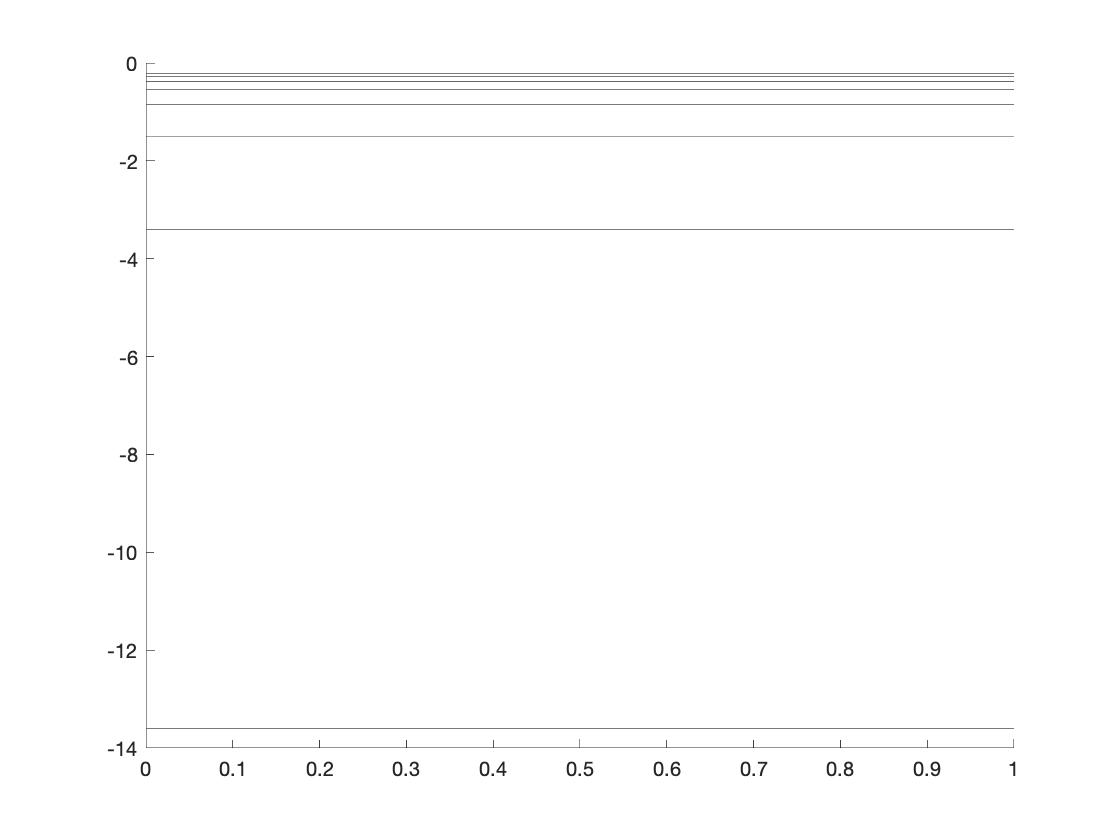

for n = 1:8
    fprintf("nivå %d har energi %.2f eV", n , E(n))
    yline(E(n));
end

### b)

finner bølgelengden for alle energinivåene fra n=3 og utover helt til vi når bølgelengder i det ultraviolette spektrum (under 400nm): 

først har vi formelen: $\lambda =\frac{h\cdot c}{E}=\frac{h\cdot c}{{E_n -E}_2 }$ dette gir:

h = 4.136 * 10^-15; %eV
c = 3.00  * 10^8;   %m/s
bolgelengden = @(n)(h*c/(E(n)-(E(2))));

starter så i energinivå 3 og går ut til energinivå 8:

for n = 3:8
    fprintf("energinivå %d gir bølgelengde %g\n", n , signif(bolgelengden(n), 3));
end

energinivå 3 gir bølgelengde 6.57e-07
energinivå 4 gir bølgelengde 4.87e-07
energinivå 5 gir bølgelengde 4.34e-07
energinivå 6 gir bølgelengde 4.11e-07
energinivå 7 gir bølgelengde 3.97e-07
energinivå 8 gir bølgelengde 3.89e-07


har også formelen:

$\frac{1}{\lambda }=1\ldotp 097*{10}^7 \left(\frac{1}{n_L^2 }-\frac{1}{n_U^2 }\right)$ dette gir $\lambda =\frac{1}{1\ldotp 097*{10}^7 \left(\frac{1}{n_L^2 }-\frac{1}{n_U^2 }\right)}\Rightarrow {\left(1\ldotp 097*{10}^7 \left(\frac{1}{4}-\frac{1}{n_U^2 }\right)\right)}^{-1}$ 

bolgelengden = @(n)((1.097*10^7)*(1/4-1/n^2))^-1;
for n = 3:8
    fprintf("energinivå %d gir bølgelengde %g\n", n , signif(bolgelengden(n), 3));
end

energinivå 3 gir bølgelengde 6.56e-07
energinivå 4 gir bølgelengde 4.86e-07
energinivå 5 gir bølgelengde 4.34e-07
energinivå 6 gir bølgelengde 4.1e-07
energinivå 7 gir bølgelengde 3.97e-07
energinivå 8 gir bølgelengde 3.89e-07


Da ser vi at det minst energirike ultraviolette fotonet vil ha en bølgelengde på 397nm. 

Dette skjer når elektronet faller fra energinivå 7 til energinivå 2.

### c)

l = 3;
L = (sqrt(l*(l+1)))*(h/(2*pi))

L =      2.280296311464532e-15


### d)

### e)

side 1400.

zeeman-effekten